# 实验二、 数字PID控制

`系统结构图如``3-1``图：`

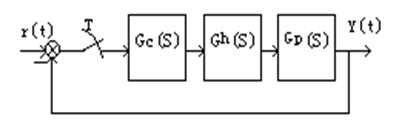

`图3-1 ``系统结构图`

`图中，`

- `控制器为PID控制器，其传递函数为`$G_c(s)=K_p(1+K_i\frac{1}{s}+K_ds）。$

- $G_h(s)$`为零阶保持器，其传递函数为`$G_h(s)=\frac{1-e^{-Ts}}{s}。$

- `被控对象分别为G``p1``（``s``）``=5/``（（``0.5s+1``）（``0.1s+1``））G``p2``（``s``）``=1/``（``s``（``0.1s+1``））。`

Gp1=tf(5,conv([0.5 1],[0.1 1]));
Gp2=tf(1,conv([1 0],[0.1 1]));

由于[MATLAB](https://www.mathworks.com/help/releases/R2021a/control/ug/discrete-time-proportional-integral-derivative-pid-controller.html)，和书本P156上的PID并列形式(parallel form)都写作如下形式，所以本脚本也使用该形式。


$$G_c(s)=K_P+K_I\frac{1}{s}+K_D{s}$$


## 一、建立MATLAB系统模型

对连续系统使用zoh法（带零阶保持器的z变换）进行离散化

Ts=0.01;
Gp1d=c2d(Gp1,Ts,'zoh');
Gp2d=c2d(Gp2,Ts,'zoh');

## 二、`确定 PID 控制器的参数`

Gc1 = pidtune(Gp1d,'PID');
Gc2 = pidtune(Gp2d,'PID');

## 三、`改变 PID 控制器的参数后的阶跃响应性能`

Tf=0;

### 3.1 对于系统一

计算闭环传递函数

names={'原PID参数下','增大Kp','增大KI','增大KD'};
Gc=pid(Gc1.Kp,Gc1.Ki,Gc1.Kd,Tf,Ts);
Phi1=feedback(series(Gc,Gp1d),1);
%增大比例环节
Gc=pid(Gc1.Kp+1,Gc1.Ki,Gc1.Kd,Tf,Ts);
Phi2=feedback(series(Gc,Gp1d),1);
%增大积分环节
Gc=pid(Gc1.Kp,Gc1.Ki+1,Gc1.Kd,Tf,Ts);
Phi3=feedback(series(Gc,Gp1d),1);
%增大微分环节
Gc=pid(Gc1.Kp,Gc1.Ki,Gc1.Kd+0.1,Tf,Ts);
Phi4=feedback(series(Gc,Gp1d),1);

绘制系统一在不同PID参数下的阶跃响应

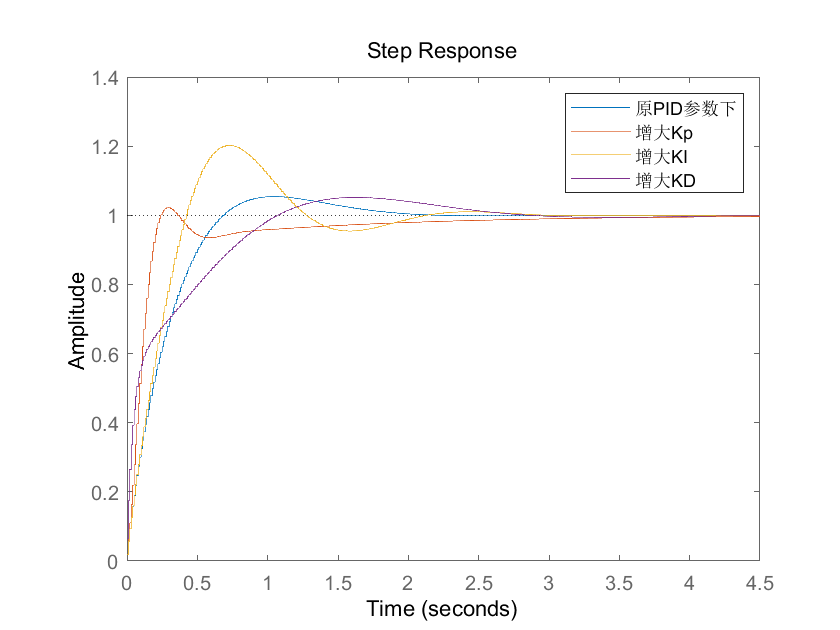

step(Phi1,Phi2,Phi3,Phi4);
legend(names);

计算阶跃相应的性能指标

s=[stepinfo(Phi1);stepinfo(Phi2);stepinfo(Phi3);stepinfo(Phi4)];
info=struct2table(orderfields(s,[5,2,1,8,3,4,7,6]),'RowNames',names');
display(info);

info = 4×8 table
                  Overshoot    SettlingTime    RiseTime    PeakTime    SettlingMin    SettlingMax     Peak     Undershoot
                  _________    ____________    ________    ________    ___________    ___________    ______    __________

    原PID参数下     5.4023          1.64          0.48        1.04        0.90771         1.054        1.054        0     
    增大Kp         2.1899          2.08          0.16        0.29        0.92163        1.0219       1.0219        0     
    增大KI         20.217          1.92          0.33        0.72        0.90962        1.2022       1.2022        0     
    增大KD         5.1593          2.38          0.75        1.62           0.91        1.0516       1.0516        0     


### 3.2 对于系统二

names={'原PID参数下','增大Kp','增大KI','增大KD'};
Gc=pid(Gc2.Kp,Gc2.Ki,Gc2.Kd,Tf,Ts);
Ph1=feedback(series(Gc,Gp2d),1);
%增大比例环节
Gc=pid(Gc2.Kp+10,Gc2.Ki,Gc2.Kd,Tf,Ts);
Ph2=feedback(series(Gc,Gp2d),1);
%增大积分环节
Gc=pid(Gc2.Kp,Gc2.Ki+10,Gc2.Kd,Tf,Ts);
Ph3=feedback(series(Gc,Gp2d),1);
%增大微分环节
Gc=pid(Gc2.Kp,Gc2.Ki,Gc2.Kd+1,Tf,Ts);
Ph4=feedback(series(Gc,Gp2d),1);

绘制系统一在不同PID参数下的阶跃响应

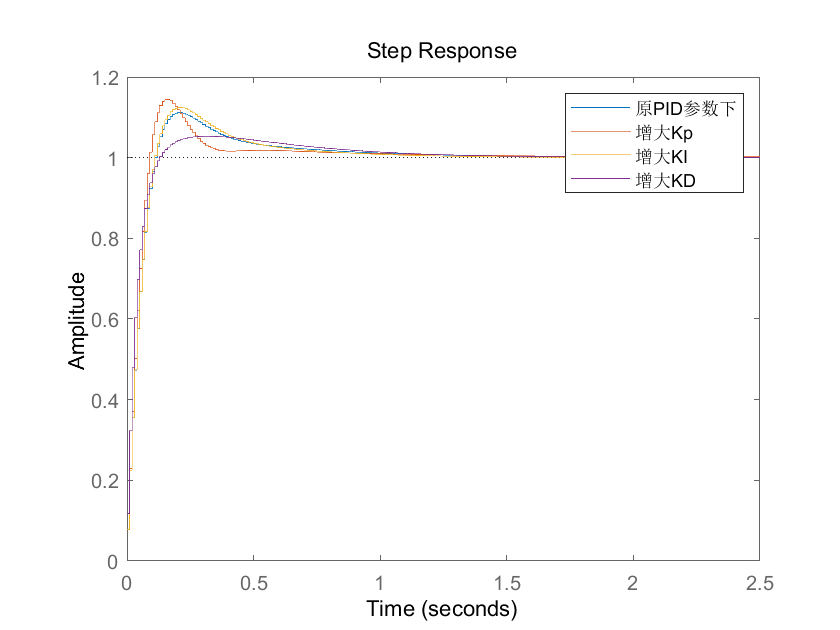

step(Ph1,Ph2,Ph3,Ph4);
legend(names);

计算阶跃相应的性能指标

s2=[stepinfo(Ph1);stepinfo(Ph2);stepinfo(Ph3);stepinfo(Ph4)];
info=struct2table(orderfields(s2,[5,2,1,8,3,4,7,6]),'RowNames',names');
display(info);

info = 4×8 table
                  Overshoot    SettlingTime    RiseTime    PeakTime    SettlingMin    SettlingMax     Peak     Undershoot
                  _________    ____________    ________    ________    ___________    ___________    ______    __________

    原PID参数下     11.174          0.78          0.08         0.2        0.92338        1.1117       1.1117        0     
    增大Kp         14.407          0.54          0.07        0.16        0.96041        1.1441       1.1441        0     
    增大KI         12.436          0.71          0.08        0.21        0.92733        1.1244       1.1244        0     
    增大KD         5.3084          0.91          0.08        0.31        0.93755        1.0531       1.0531        0     


### 3.3 分析控制效果

不同环节对系统的控制作用不同，PID的三个环节对于控制效果的影响可以概括如下：

- 比例环节：成比例地反映控制系统的偏差信号e(t)，偏差一旦产生，控制器立即产生控制作用，以减小偏差。

- 积分环节：主要用于消除静差，提高系统的无差度。积分作用的强弱取决于积分时间常数T,T越大，积分作用越弱，反之则越强。

- 微分环节：反映偏差信号的变化趋势，并能在偏差信号变得太大之前，在系统中引入一个有效的早期修正信号，从而加快系统的动作速度，减少调节时间。

## 四、PID改进算法

Simulink 的PID模块提供两种内置的抗饱和方法（`back-calculation` 和 `clamping`），还提供一种跟踪模式来处理更复杂的场景。可以参考[使用 PID 控制器进行抗饱和控制 - MATLAB & Simulink - MathWorks 中国](https://ww2.mathworks.cn/help/simulink/slref/anti-windup-control-using-a-pid-controller.html)，这里使用Simulink交互命令简单进行演示（[Run Simulations Programmatically - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/simulink/ug/using-the-sim-command.html)）。

首先需要在PID模块的Output Saturation中设置输出限制Limit Output，来产生饱和，再设计相应的抗饱和算法。

labels=["u","抗饱和后u1","y","抗饱和后y1"];

### **4.1 基于反算配置抗饱和模块**

    从图中可以看出，加入抗饱和算法之后，饱和时间明显变小，控制的超调量也明显变小。

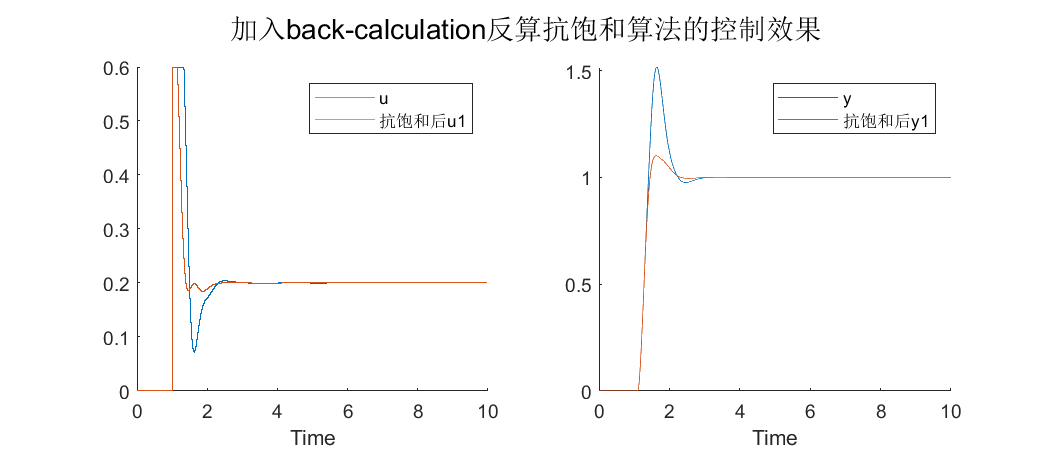

simOut = sim('antiwindupPIDmodel1.slx','SimulationMode','normal','AbsTol','1e-5',...
            'SaveOutput','on','OutputSaveName','yout','SaveFormat', 'Dataset');
outputs = simOut.get('yout');
u = (outputs.get('u').Values);
y = (outputs.get('y').Values);
u1= (outputs.get('u1').Values);
y1= (outputs.get('y1').Values);
figure('Position',[0,0,700,300]);

subplot(1,2,1);hold on;
plot(u);
plot(u1);
xlabel('Time'); legend(labels(1:2))
subplot(1,2,2);hold on;
plot(y);
plot(y1);
xlabel('Time'); legend(labels(3:4));
sgtitle('加入back-calculation反算抗饱和算法的控制效果');

### 4.2**基于积分器钳位配置抗饱和模块**

    从图中可以看出，使用抗饱和算法之后，系统震荡明显减弱，更快进入稳定状态

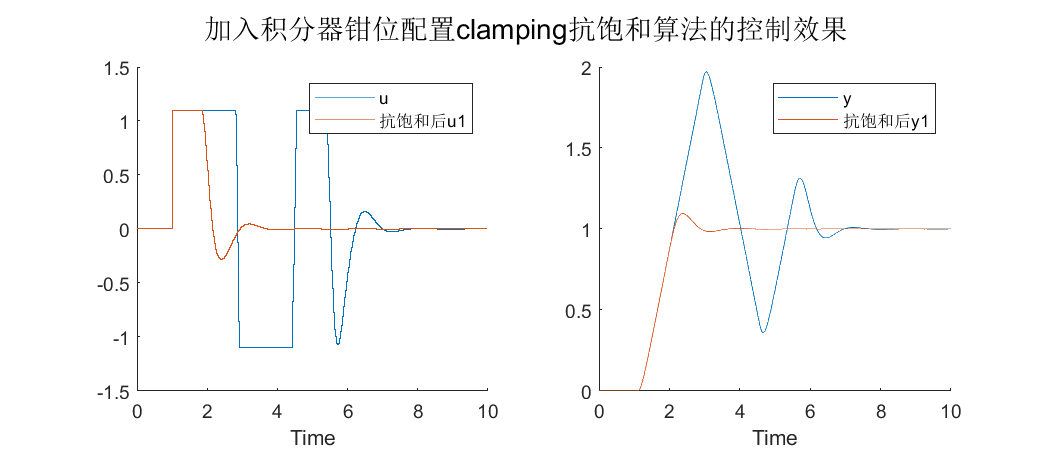

simOut = sim('antiwindupPIDmodel2.slx','SimulationMode','normal','AbsTol','1e-5',...
            'SaveOutput','on','OutputSaveName','yout','SaveFormat', 'Dataset');
outputs = simOut.get('yout');
u = (outputs.get('u').Values);
y = (outputs.get('y').Values);
u1= (outputs.get('u1').Values);
y1= (outputs.get('y1').Values);
figure('Position',[0,0,700,300]);

subplot(1,2,1);hold on;
plot(u);
plot(u1);
xlabel('Time'); legend(labels(1:2))
subplot(1,2,2);hold on;
plot(y);
plot(y1);
xlabel('Time'); legend(labels(3:4));
sgtitle("加入积分器钳位配置clamping抗饱和算法的控制效果");